data = data81;
ndata = zeros(32400,6)

ndata =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


for i = 1:7
    ndata(:,i) = (data(:,i)-min(data(:,i)))./(max(data(:,i))-min(data(:,i)));
end
pn = [ndata(:,1:4) ndata(:,7)];
tn = ndata(:,5);

net0 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 1
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      input

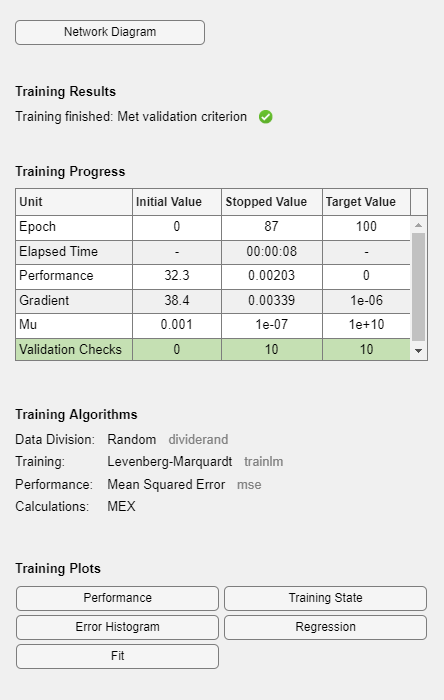

for n=1:50                               %number of neuron
net0 = fitnet(n,'trainlm');              %fitnet(hiddenlayersize,training function)
net0.divideParam.trainRatio  = 0.8;
net0.divideParam.valRatio    = 0.2;
net0.divideParam.testRatio   = 0;
net0.trainParam.epochs       = 100;      %Maximum number of epochs to train. The default value is 1000.
net0.trainParam.goal         = 0;        %Performance goal. The default value is 0
net0.trainParam.max_fail     = 10;       %Maximum validation failures. The default value is 6.
net0.trainParam.min_grad     = 1e-06;    %Minimum performance gradient. The default value is 1e-5.
net0.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.
net0.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net0.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net0.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net0.inputs{1}.processFcns   = {'removeconstantrows'};
net0.outputs{2}.processFcns  = {'removeconstantrows'};
net.layers{1}.transferFcn = 'poslin';

[net0,tr0] = train(net0,pn',tn');
mse_val0(n)= tr0.best_vperf;
[M0,I0] = min(mse_val0);        % update the latest minimum mse value (M0) with its index (I0)
end


plot(mse_val0,'-');

disp('training index of best MSE value set is')

training index of best MSE value set is


disp(I0)

    24



disp('Which has MSE =')

Which has MSE =


disp(M0)

    0.0020



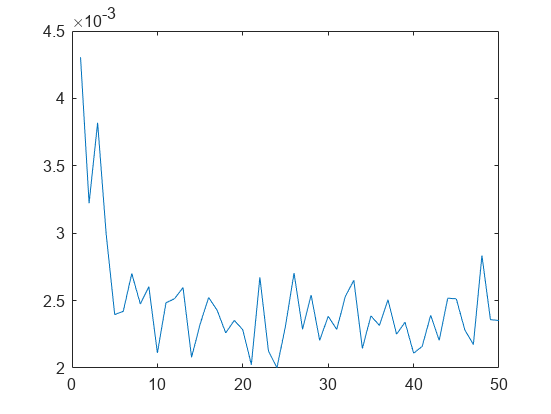

hold off;

net1 = fitnet(100,'trainlm');              %fitnet(hiddenlayersize,training function)
net1.divideParam.trainRatio  = 0.8;
net1.divideParam.valRatio    = 0.2;
net1.divideParam.testRatio   = 0;
net1.trainParam.epochs       = 1000;      %Maximum number of epochs to train. The default value is 1000.
net1.trainParam.goal         = 0;        %Performance goal. The default value is 0.
net1.trainParam.lr           = 0.001;     %Learning rate. The default value is 0.01.
net1.trainParam.max_fail     = 100;       %Maximum validation failures. The default value is 6.
net1.trainParam.min_grad     = 1e-6;    %Minimum performance gradient. The default value is 1e-5.
net1.trainParam.show         = 100       %Epochs between displays (NaN for no displays). The default value is 25.

net1 =

    Neural Network
 
              name: 'Function Fitting Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 2
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 100
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1]
      inp

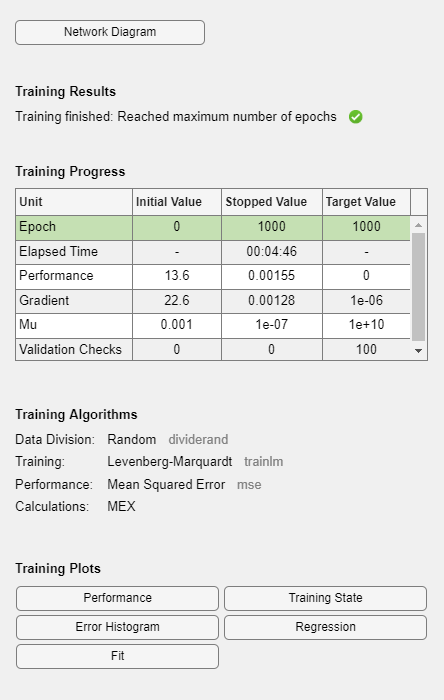

net1.trainParam.showWindow   = true;     %Show training GUI. The default value is true.
net1.trainParam.time         = inf;      %Maximum time to train in seconds. The default value is inf.
net1.performFcn              = 'mse';    %There are mae mse sae sse available in MATLAB
net1.inputs{1}.processFcns   = {'removeconstantrows'};
net1.outputs{2}.processFcns  = {'removeconstantrows'};
net1.layers{1}.transferFcn = 'tansig';

[net1,tr1] = train(net1,pn',tn');

ans=net1(pn')'

ans =     0.3849
    0.4137
    0.4401
    0.4618
    0.4726
    0.4554
    0.3788
    0.2329
    0.0902
    0.0165


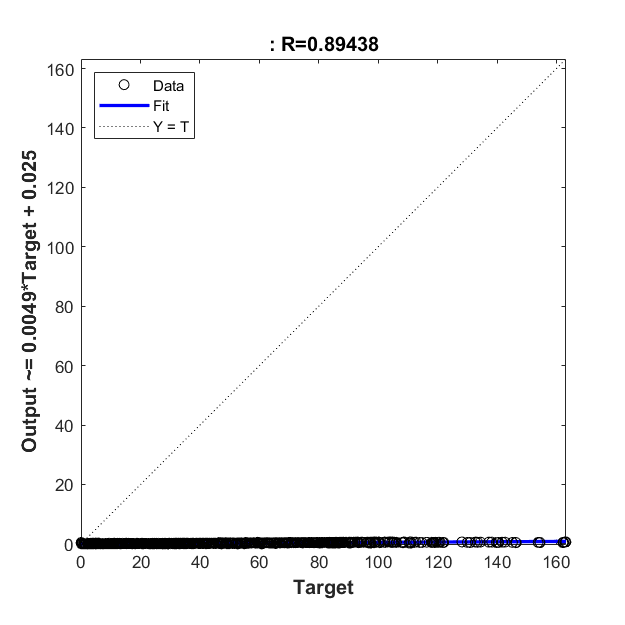

%ans = (ans.*(max(data(:,5))-min(data(:,5)))+min(data(:,5)))
plotregression(data(:,5),ans)

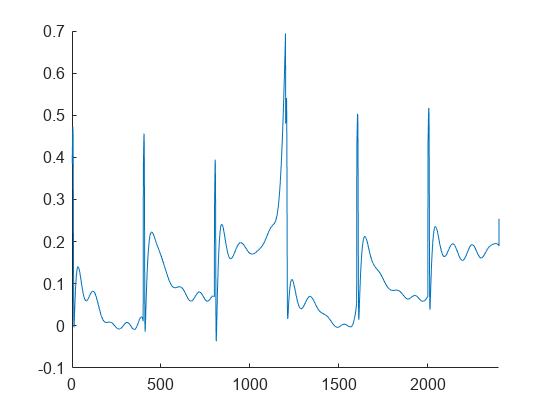

figure()
%plot(data(:,5))
hold on;
plot(ans);
xlim([0 2400])

ntest = zeros(2000,6)

ntest =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


for i = 1:4
    ntest(:,i) = (testing(:,i)-min(data(:,i)))./(max(data(:,i))-min(data(:,i)));
end
ntest(:,5) = (testing(:,5)-min(data(:,7)))./(max(data(:,7))-min(data(:,7)));
ntest(:,6) = (testing(:,6)-min(data(:,5)))./(max(data(:,5))-min(data(:,5)));

pntest = ntest(:,1:5);
tntest = ntest(:,6);

ans=net1(pntest')'

ans =   -14.6619
  -14.5097
  -14.3701
  -14.2636
  -14.2227
  -14.2401
  -14.2310
  -14.1499
  -14.0221
  -13.8752


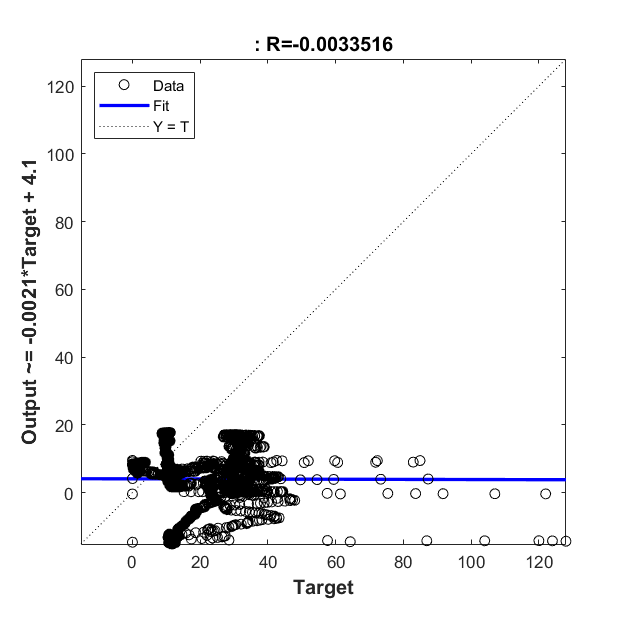

%ans = (ans).*(max(data(:,5))-min(data(:,5)))+min(data(:,5))
plotregression(testing(:,6),ans)

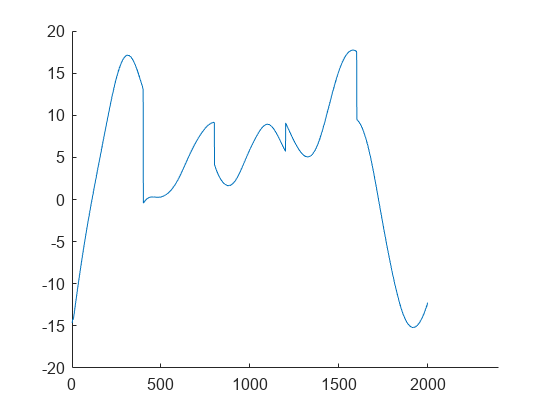

figure()
%plot(testing(:,6))
hold on;
plot(ans);
xlim([0 2400])


ans=net1(pn')'

ans =     0.5494    0.0102    0.0869
    0.5535    0.4653    0.3531
    0.5519    0.7990    0.6161
    0.5592    0.0275    0.0860
    0.5607    0.3950    0.3215
    0.5619    0.7522    0.5534
    0.5667   -0.0324    0.0581
    0.5679    0.3247    0.2900
    0.5669    0.6567    0.5388
    0.7652    0.0597    0.1816


IPF = (ans(:,1).*(max(data(:,5))-min(data(:,5)))+min(data(:,5)))

IPF =   119.0604
  119.4564
  119.3038
  120.0190
  120.1645
  120.2803
  120.7569
  120.8727
  120.7754
  140.2014


EA  = (ans(:,2).*(max(data(:,6))-min(data(:,6)))+min(data(:,6)))

EA = 1.0e+03 *

    2.0319
    5.6821
    8.3582
    2.1707
    5.1186
    7.9831
    1.6904
    4.5550
    7.2175
    2.4294


Mass= (ans(:,3).*(max(data(:,7))-min(data(:,7)))+min(data(:,7)))

Mass =     2.1998
    3.3764
    4.5388
    2.1959
    3.2369
    4.2617
    2.0725
    3.0974
    4.1972
    2.6184


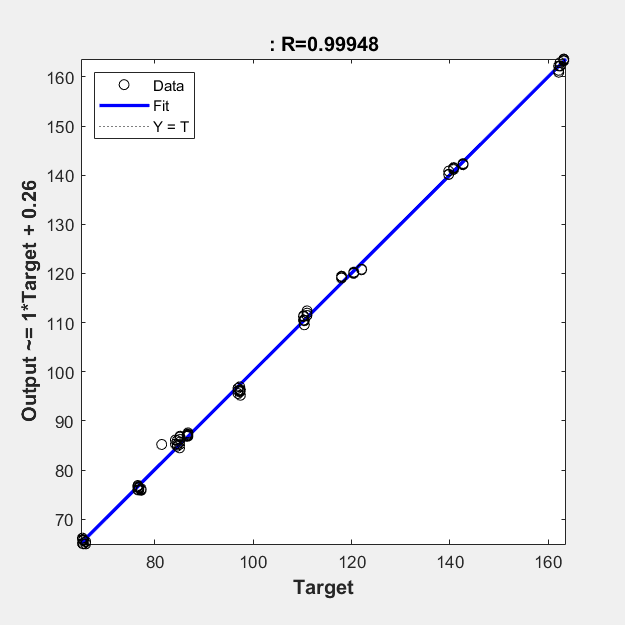

plotregression(data(:,5),IPF)

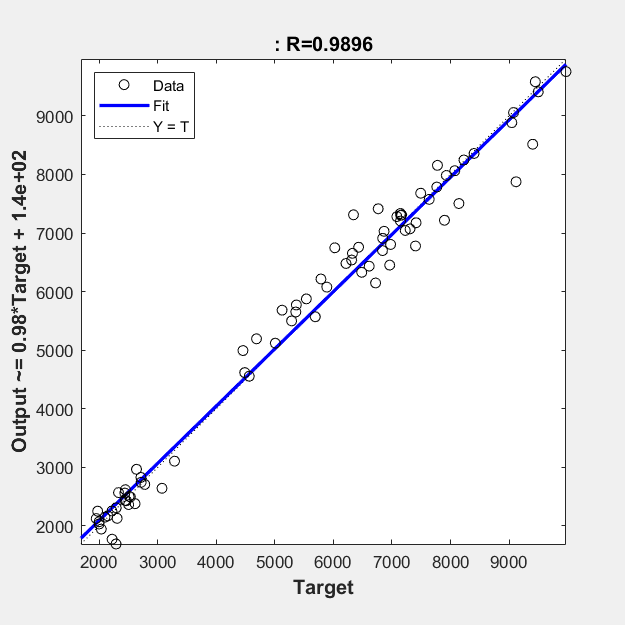

pause(1);
plotregression(data(:,6),EA)

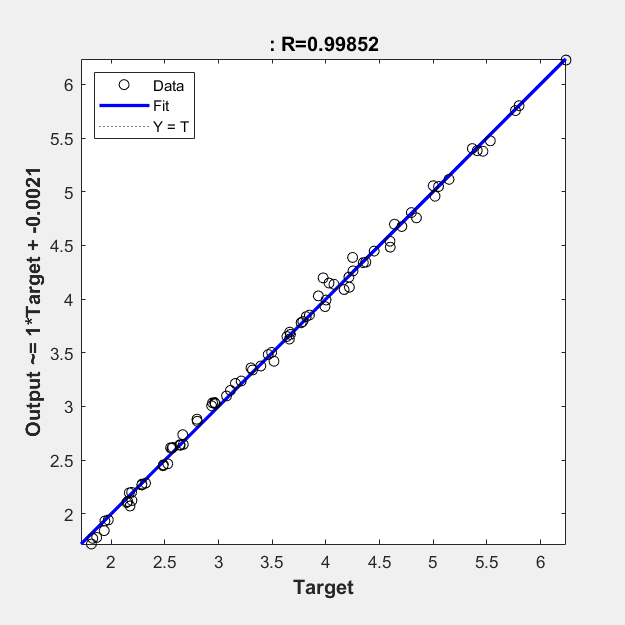

pause(1);
plotregression(data(:,7),Mass)